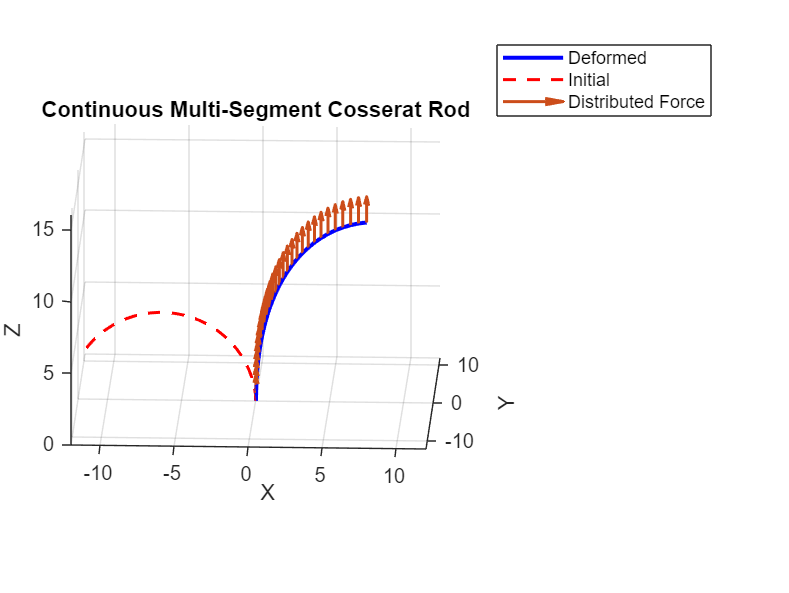

%This is a test file for beam bending simulation

%TODO:
%Implementing distributed force
%Implementing multiple segments

clear, close all

% Parameters
EI = 3;         % Bending stiffness
GJ = .7;
r = 5 / pi;        % Robot radius
n = 1;             % Number of segments
N = 30;         % Number of discretization points
N_d = 2;            % Number of points to estimate distributed force




% Initial actuator positions
act_11_start = [r; 0; 0; 1];
act_12_start = [r*cos(2*pi/3); r*sin(2*pi/3); 0; 1];
act_13_start = [r*cos(4*pi/3); r*sin(4*pi/3); 0; 1];
Base_coord = eye(4);


%Force applied at tip, N
Fx = 0; 
Fy = 0.00; 
Fz = 0.00;

%Moment applied at tip
Mx = 0;
My = 0;
Mz = 0;

%Actuator Lengths
L1 = 4;
L2 = 6;
L3 = 6;
Lck = (L1+L2+L3)/3;

%Turn plot on or off
ploton = false;


simple_f = @(s) [0*s; 0*s; 0*s];  % No dist force
dist_f = @(s) [.01*s; .00*s; -.006*s];  % gravity in -Z
s_force = linspace(0, Lck, N); % same arc length as beam
s_force_d = linspace(0, Lck, N_d);  % force estimation points
%Input function for testing
%[p_def,p_init] = bending_3D(EI,GJ,r,N,L1,L2,L3,act_11_start,act_12_start,act_13_start,Base_coord,.03,0,-.04,Mx,My,Mz,s_force,simple_f,true);
m = 3;          % Number of segments

% ----------------------------
% Segment parameters
% ----------------------------
% L1, L2, L3 are "actuator" lengths for each segment
L1_all = [4, 4,4];   % segment 1 & 2
L2_all = [6, 6,6];
L3_all = [6, 6,6];
L_ck_all = (L1_all+L2_all+L3_all)/3;

% Base coordinates
Base_coord = [0;0;0];

% External forces per segment (global frame)
Fx_all = .0;
Fy_all = .0;
Fz_all = -.0;
Mx_all = [0, 0,0];
My_all = [0, 0,0];
Mz_all = [0, 0,0];

% Total backbone length
L_total = sum(L_ck_all);

% Single sinusoidal distributed force along the entire rod
F_amp = 0.5;  % peak amplitude
dist_force_fun = @(s) [0; 0; .01];

% ----------------------------
% Run simulation
% ----------------------------
[p_def_all, p_init_all] = bending_3D_multi_continuous( ...
    EI,GJ,r,N, ...
    L1_all,L2_all,L3_all, ...
    Base_coord, ...
    Fx_all,Fy_all,Fz_all, ...
    Mx_all,My_all,Mz_all, ...
    [],dist_force_fun, true);



%For now, I will use the function twice to generate two sets of points for
%two sensed actuator length sets

[p_pred,~] = bending_3D(EI,GJ,r,N,L1,L2,L3,act_11_start,act_12_start,act_13_start,Base_coord,0,0,0,Mx,My,Mz,s_force,simple_f,ploton);

Unrecognized function or variable 'bending_3D'.


[p_act,~] = bending_3D(EI,GJ,r,N,3,6.5,6.5,act_11_start,act_12_start,act_13_start,Base_coord,0,0,0,Mx,My,Mz,s_force,simple_f,ploton);


lambda = .1;                   % regularization weight


% Observed shape
p_target = p_act;

fun = @(x) objective_with_reg_Nd(x, p_target, EI, GJ, r, N, N_d, ...
            L1, L2, L3, act_11_start, act_12_start, act_13_start, ...
            Base_coord, Mx, My, Mz, s_force_d, s_force, lambda);
%Given input xdata and observed output ydata, find x
%x0 = [0; 0; 0];

x0 = 0.0*randn(3*N_d, 1);

lb = -1*ones(3*N_d,1);
ub = 1*ones(3*N_d,1);
% Fix base force components to zero:
lb(1:3) = 0;
ub(1:3) = 0;

options = optimoptions(@lsqnonlin, ...
    'Algorithm', 'trust-region-reflective', ...
    'MaxIterations', 50, ...
    'Display', 'iter-detailed', ...
    'StepTolerance', 1e-4, ...
    'FunctionTolerance', 4e-2, ...
    'FiniteDifferenceType', 'central', ...
    'SpecifyObjectiveGradient', false); 



tic
% Solve

x_est = lsqnonlin(fun, x0, lb, ub, options);
toc



%Post processing
% Forces at the N_d estimation points (3 x N_d)
f_dist_est_d = reshape(x_est, 3, N_d);

% f_dist_est_d = [0 0 0 0 0 0
%                 0 0 0 0 0 0
%                 0 0 0 0 0 0];

% Build full 3xN force matrix with zeros except at nearest N_d nodes
f_dist_est = zeros(3, N);
force_idxs = zeros(1, N_d);


%This is a bit stupid but the other way didnt work
for i = 1:N_d
    [~, force_idxs(i)] = min(abs(s_force - s_force_d(i)));
    f_dist_est(:, force_idxs(i)) = f_dist_est_d(:, i);
end

%f_dist_est(:,1) = [0;0;0]

% Forward solve
[p_act_2, ~] = bending_3D(EI, GJ, r, N, ...
    L1, L2, L3, ...
    act_11_start, act_12_start, act_13_start, ...
    Base_coord, ...
    0, 0, 0, ...
    Mx, My, Mz, ...
    s_force, f_dist_est, ...  
    ploton);

% --- Plot shapes ---
figure
plot3(p_pred(1,:), p_pred(2,:), p_pred(3,:), 'g-', 'LineWidth', 2); hold on;
plot3(p_act(1,:),  p_act(2,:),  p_act(3,:),  'r-', 'LineWidth', 2);
plot3(p_act_2(1,:), p_act_2(2,:), p_act_2(3,:), 'b-', 'LineWidth', 2);

title('Initial (Zero-Force) Curved Shape');

% --- Plotting distributed force arrows at the N_d locations only ---
max_arrow_length = 1;  
mag_nd = vecnorm(f_dist_est_d, 2, 1);             % 1 x N_d
max_force_mag = max(mag_nd) + 1e-9;               % avoid /0
scale_factor = max_arrow_length / max_force_mag;

for j = 1:N_d
    idx = force_idxs(j);                           % nearest backbone node
    pos = p_act_2(:, idx);
    f_vec = f_dist_est_d(:, j);

    f_mag = mag_nd(j);
    if f_mag > 0
        f_dir = f_vec / f_mag;
        L = scale_factor * f_mag;
        quiver3(pos(1), pos(2), pos(3), ...
                L*f_dir(1), L*f_dir(2), L*f_dir(3), ...
                'Color', [0.8 0.3 0.1], ...
                'LineWidth', 1.5, ...
                'MaxHeadSize', 2);
    end
end

xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;
xlim([-6 6]); ylim([-6 6]); zlim([0 8]);
title('3D Backbone Shape from bvp4c');
legend('Predicted Shape','Measured Shape','Shape based on Estimated Force','Estimated Force', ...
       'Location', 'best');
hold off


Functions

function err = objective_with_reg_Nd(x, p_target, EI, GJ, r, N, N_d, ...
                                  L1,L2,L3, act_11_start, act_12_start, act_13_start, ...
                                  Base_coord, Mx, My, Mz, s_force_d, s_force, lambda)

    % Force values only at N_d points
    f_dist_vec_d = reshape(x, 3, N_d);

    % Make a full N-point force array of zeros
    f_dist_vec_full = zeros(3, N);
    
    % Map each of the N_d estimated forces to the nearest s_force index
    for i = 1:N_d
        [~, idx] = min(abs(s_force - s_force_d(i)));
        f_dist_vec_full(:, idx) = f_dist_vec_d(:, i);
    end

    % Pass to bending_3D
    [p_pred, ~] = bending_3D(EI, GJ, r, N, ...
                         L1, L2, L3, ...
                         act_11_start, act_12_start, act_13_start, ...
                         Base_coord, ...
                         0, 0, 0, ...
                         Mx, My, Mz, ...
                         s_force, f_dist_vec_full, false);

    % Residuals
    data_residual = p_pred(:) - p_target(:);

    % Regularization (on the reduced N_d vector)
    f_ddx = f_dist_vec_d(:,1:end-2) - 2*f_dist_vec_d(:,2:end-1) + f_dist_vec_d(:,3:end);
    reg_penalty = lambda * f_ddx(:);

    err = [data_residual; reg_penalty];
end

%Main function, gives deformed shape based on input force/moment and
%initial shape
%% ---------------------------
%% Multi-segment wrapper
%% ---------------------------
%% ---------------------------
%% ---------------------------
%% Multi-segment wrapper (corrected)
%% ---------------------------
%% ---------------------------
%% Single BVP for multi-segment rod
%% ---------------------------
function [p_def, p_init, R_end] = bending_3D_multi_continuous(EI, GJ, r, ...
    N, L1_all, L2_all, L3_all, Base_coord, ...
    Fx_all, Fy_all, Fz_all, Mx_all, My_all, Mz_all, ...
    s_force_all, f_dist_vec_all, ploton)

%% ---------------------------
%% Continuous backbone setup
%% ---------------------------

m = length(L1_all);          % number of segments
L_seg = (L1_all + L2_all + L3_all)/3;
L_total = sum(L_seg);        % total backbone length

s_vals = linspace(0, L_total, N);  % global arc-length discretization

%% ---------------------------
%% Initialize intrinsic curvature along the rod
%% ---------------------------
kappa0_vals = zeros(3,N);
s_offset = 0;

for seg = 1:m
    [~, ~, Lck, beta, theta] = gen_transform_2(L1_all(seg), L2_all(seg), L3_all(seg), r, []);
    curvature = beta / Lck;
    
    % Local segment arc (discretize segment)
    N_seg = round(N * Lck / sum((L1_all + L2_all + L3_all)/3)); % proportional nodes
    s_seg = linspace(0, Lck, N_seg);
    
    % Local curvature in segment frame (signed)
    kappa_seg = [curvature.*cos(theta-pi/2) * ones(1,N_seg);
                 curvature.*sin(theta-pi/2) * ones(1,N_seg);
                 zeros(1,N_seg)];
    
    % Map segment curvature to global backbone
    idx_start = find(s_vals >= s_offset, 1, 'first');
    idx_end   = find(s_vals <= s_offset + Lck, 1, 'last');
    
    kappa0_vals(:, idx_start:idx_end) = kappa_seg(:,1:(idx_end-idx_start+1));
    s_offset = s_offset + Lck;
end


if isa(f_dist_vec_all,'function_handle')
    dist_force_fun = f_dist_vec_all;
else
    dist_force_fun = @(s) interp1(s_force, f_dist_vec', s, 'linear', 'extrap')';
end

%% ---------------------------
%% BVP parameters
%% ---------------------------
params.Kb = EI*eye(3);
params.Kt = GJ;
params.p_base = Base_coord(:);
params.R_base = eye(3);
params.kappa0_fun = @(s) interp1(s_vals', kappa0_vals', s, 'linear', 'extrap')';
params.n_tip = [sum(Fx_all); sum(Fy_all); sum(Fz_all)];
params.m_tip = [sum(Mx_all); sum(My_all); sum(Mz_all)];
params.distributed_force_fun = dist_force_fun;

%% ---------------------------
%% Initial guess
%% ---------------------------
solinit = bvpinit(s_vals,@(s) cosserat_rod_guess(s,params));

%% ---------------------------
%% Solve BVP
%% ---------------------------
sol = bvp4c(@(s,y) cosserat_rod_ode(s,y,params), ...
            @(ya,yb) cosserat_rod_bc(ya,yb,params), solinit);

y_sol = deval(sol,s_vals);

p_def = y_sol(1:3,:);
R_end = reshape(y_sol(4:12,end),3,3);

%% ---------------------------
%% Force-free initial shape
%% ---------------------------
p_init = zeros(3,N);
R_init = zeros(3,3,N);
p_init(:,1) = Base_coord(:);
R_init(:,:,1) = eye(3);

for i = 2:N
    ds = s_vals(i) - s_vals(i-1);
    kappa_prev = params.kappa0_fun(s_vals(i-1));
    
    ang = norm(kappa_prev)*ds;
    if ang < 1e-12
        R_step = eye(3) + skew(kappa_prev*ds);
    else
        u = kappa_prev/(norm(kappa_prev)+eps);
        Khat = skew(u);
        R_step = eye(3) + sin(ang)*Khat + (1-cos(ang))*(Khat*Khat);
    end
    
    R_init(:,:,i) = R_init(:,:,i-1) * R_step;
    t_global = R_init(:,3,i);
    p_init(:,i) = p_init(:,i-1) + t_global*ds;
end

%% ---------------------------
%% Plot
%% ---------------------------
if ploton
    figure;
    plot3(p_def(1,:), p_def(2,:), p_def(3,:), 'b-', 'LineWidth',2); hold on;
    plot3(p_init(1,:), p_init(2,:), p_init(3,:), 'r--','LineWidth',1.5);
    axis equal; grid on; xlabel('X'); ylabel('Y'); zlabel('Z');
    xlim([-12 12]);ylim([-12 12]);zlim([0 16]);

     %Plotting distributed force
         % Plot distributed forces along the rod
        %force_scale = .5;  % adjust scale for visibility
        num_force_vectors = N;  % number of force vectors to plot
        idxs = round(linspace(1, N, num_force_vectors));
         % Evaluate distributed force magnitude at multiple points
        f_mags = zeros(1, length(idxs));
        for j = 1:length(idxs)
            s = s_vals(idxs(j));
            f_mags(j) = norm(dist_force_fun(s));
        end
    
        % Determine a global scale factor so arrows are visually reasonable
        max_arrow_length = 2;  % max arrow size in plot units
        max_force_mag = max(f_mags) + 1e-6;  % avoid divide-by-zero
        scale_factor = max_arrow_length / max_force_mag;

         % Plot each arrow
        for j = 1:length(idxs)
            i = idxs(j);
            s = s_vals(i);
            pos = p_def(:, i);
            f_vec = dist_force_fun(s);
    
            % Normalize direction, scale by local magnitude
            f_mag = norm(f_vec);
            f_dir = f_vec / (f_mag + 1e-6);  % unit vector
            arrow_length = scale_factor * f_mag;
    
            % Plot arrow
            quiver3(pos(1), pos(2), pos(3), ...
                    arrow_length * f_dir(1), ...
                    arrow_length * f_dir(2), ...
                    arrow_length * f_dir(3), ...
                    'Color', [0.8 0.3 0.1], ...
                    'LineWidth', 1.5, ...
                    'MaxHeadSize', 2);
        end


    legend('Deformed','Initial','Distributed Force'); title('Continuous Multi-Segment Cosserat Rod');
end
end


%% Continuous rod BC
function res = cosserat_rod_bc(ya, yb, params)
    res = zeros(18,1);
    % Base fixed
    res(1:3) = ya(1:3) - params.p_base;
    res(4:12) = ya(4:12) - reshape(params.R_base,9,1);
    % Tip force/moment
    res(13:15) = yb(13:15) - params.n_tip;
    res(16:18) = yb(16:18) - params.m_tip;
end




%% ---------------------------
%% Cosserat ODE (global-state convention)
%% y = [p(1:3); R(:); n(13:15); m(16:18)]
%% ---------------------------
function dy = cosserat_rod_ode(s, y, params)
    Kb = params.Kb;

    % unpack state
    p = y(1:3);
    R = reshape(y(4:12), 3, 3);
    n = y(13:15);
    m = y(16:18);

    % tangent in global frame: third column of R
    t = R(:,3);

    % intrinsic curvature in body frame
    kappa0 = params.kappa0_fun(s);
    
    % constitutive: m = Kb*(kappa - kappa0)  =>  kappa = kappa0 + inv(Kb)*m
    kappa = Kb \ (m - Kb * kappa0);

    % kinematics
    dp_ds = t;
    dR_ds = R * skew(kappa);

    % distributed force (global)
    f_dist = params.distributed_force_fun(s);
  

    % statics (global)
    dn_ds = -f_dist;
    dm_ds = -cross(t, n);

    % pack derivatives
    dy = zeros(18,1);
    dy(1:3)    = dp_ds;
    dy(4:12)   = reshape(dR_ds, 9, 1);
    dy(13:15)  = dn_ds;
    dy(16:18)  = dm_ds;
end



%% ---------------------------
%% Initial guess for BVP (anchored to base)
%% ---------------------------
function yinit = cosserat_rod_guess(s, params)
    % Interpolate intrinsic curvature at s
    kappa0 = params.kappa0_fun(s);
    
    % Integrate to get tangent vector (approximate)
    % Assuming constant theta and beta along s for simplicity
    beta_val = norm(kappa0) * s;  % angle of bending up to s
    if beta_val < 1e-6
        tangent = [0;0;1]; % nearly straight
    else
        theta_val = atan2(kappa0(2), kappa0(1));
        tangent = [sin(beta_val)*cos(theta_val);
                   sin(beta_val)*sin(theta_val);
                   cos(beta_val)];
    end
    
    % Approximate position
    p = tangent * s; % linear approx; you can improve by integrating

    % Approximate rotation: identity for simplicity
    R = eye(3);

    % Guess internal forces and moments
    n = params.n_tip;
    m = params.m_tip;

    yinit = [p; reshape(R,9,1); n; m];
end

%% ---------------------------
%% Kinematic transform from actuator lengths
%% (kept consistent with your original implementation)
%% ---------------------------
function [T_k, rho_k,L_ck,beta_k,theta_k] = ...
    gen_transform_2(L_k1, L_k2, L_k3, r, T_prev)

    % Compute average length
    L_ck = (L_k1 + L_k2 + L_k3)/3;

    % Compute bending magnitude (beta)
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);

    % Compute azimuth angle theta based on actuator differences
    % This ensures the bending direction points along the resultant of actuators
    x = L_k1 - (L_k2 + L_k3)/2;
    y = (sqrt(3)/2)*(L_k2 - L_k3);
    theta_k = atan2(y, x);  % angle in XY plane

    % Curvature per unit length
    rho_k = beta_k / L_ck;

    % Precompute trig terms
    ct = cos(theta_k); st = sin(theta_k);
    cb = cos(beta_k); sb = sin(beta_k);

    % Rotation matrix from local to previous frame
    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position along previous frame
    if abs(rho_k) < 1e-12
        P_k = [0;0;L_ck];
        T_k = [eye(3) P_k; 0 0 0 1];
    else
        P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];
        T_k = [R_k P_k; 0 0 0 1];
    end
end


%% ---------------------------
%% Skew (hat) operator
%% ---------------------------
function S = skew(v)
    S = [   0   -v(3)  v(2);
          v(3)    0   -v(1);
         -v(2)  v(1)    0 ];
end
